# **AUTOMATED SIMULATION**

In this file we are going to analize two kind of controllers. In the first part we deal with anti-windup and feedforward, while in the second one we exploit the power of state-space techniques. This forst section clears the workspace and loads all the paramters that aree needed to perform simulations.

clear all
clc;

load('parameters.mat');

simul.select1 = 1;      % takes values in {1, 2,3} = {deg, rpm, rpm/s} reference
simul.select2 = 1;      % takes values in {1, 2, 3} = {step, stair, ramp}
simul.select3 = 1;      % takes values in {1, 2} = {sinusoidal, step} used for error space and extended estimator
simul.stair_gain = 1;   % takes values in {-1, 1}
simul.ramp_gain = 1;    % takes values in [0,1]
simul.stepdeg = 0;      % sets the step amplitude of the deg step
simul.antiWindUp = 1;   % takes values in {-1, 1} -1 anti-windup loop deactivated 1 activated

warning('off','all')

### **[2.1] ANTI-WINDUP**

simul.FFW = 0;          % deactivating Feed-Forward
simul.select1 = 1;      % takes values in {1, 2,3} = {deg, rpm, rpm/s} reference
simul.select2 = 1;      % takes values in {1, 2, 3} = {step, stair, ramp}
simul.stepdeg = 360;

%PID values that make with and without Anti-WindUp simulations respect
%required settling time specifications
pid.K = 20;
pid.Kd = 0.15;
pid.Ki = 2;

Simulation with suggested Anti-WindUp constant

awu.a = 5;              % this should be adjusted
awu.Tw = perf.ts5/awu.a;
awu.Kw = 1/awu.Tw;

# DO SIMULATION

%anti_windup.step_suggested = sim('lab1_PID','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
anti_windup.step_suggested.al_meas = al_meas;
anti_windup.step_suggested.aref = aref;
anti_windup.step_suggested.e = e;
anti_windup.step_suggested.ia = ia;
anti_windup.step_suggested.thl_meas = thl_meas;
anti_windup.step_suggested.thref = thref;
anti_windup.step_suggested.u = u;
anti_windup.step_suggested.wl_meas = wl_meas;
anti_windup.step_suggested.wref = wref;
anti_windup.step_suggested.pid = pid;
anti_windup.step_suggested.awu = awu;
anti_windup.step_suggested.simul = simul;

Simulation with adequate Anti-WindUp Constant

awu.a = 0.1;              % this should be adjusted
awu.Tw = perf.ts5/awu.a;
awu.Kw = 1/awu.Tw;

# DO SIMULATION

%anti_windup.step = sim('lab1_PID','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
anti_windup.step.al_meas = al_meas;
anti_windup.step.aref = aref;
anti_windup.step.e = e;
anti_windup.step.ia = ia;
anti_windup.step.thl_meas = thl_meas;
anti_windup.step.thref = thref;
anti_windup.step.u = u;
anti_windup.step.wl_meas = wl_meas;
anti_windup.step.wref = wref;
anti_windup.step.pid = pid;
anti_windup.step.awu = awu;
anti_windup.step.simul = simul;

stepinfo(anti_windup.step.thl_meas.signals.values,anti_windup.step.thref.time,simul.stepdeg, 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
         RiseTime: 0.1107
    TransientTime: 1.1522
     SettlingTime: 1.1522
      SettlingMin: 324.7200
      SettlingMax: 357.6600
        Overshoot: 0
       Undershoot: 0
             Peak: 357.6600
         PeakTime: 19.7810


Simulation without Anti-WindUp

awu.Kw = 0;        % Disable Anti windup

# DO SIMULATION


%anti_windup.OFF_step = sim('lab1_PID','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
anti_windup.OFF_step.al_meas = al_meas;
anti_windup.OFF_step.aref = aref;
anti_windup.OFF_step.e = e;
anti_windup.OFF_step.ia = ia;
anti_windup.OFF_step.thl_meas = thl_meas;
anti_windup.OFF_step.thref = thref;
anti_windup.OFF_step.u = u;
anti_windup.OFF_step.wl_meas = wl_meas;
anti_windup.OFF_step.wref = wref;
anti_windup.OFF_step.pid = pid;
anti_windup.OFF_step.awu = awu;
anti_windup.OFF_step.simul = simul;
stepinfo(anti_windup.OFF_step.thl_meas.signals.values,anti_windup.OFF_step.thref.time,simul.stepdeg, 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
         RiseTime: 0.1101
    TransientTime: 1.1497
     SettlingTime: 1.1497
      SettlingMin: 325.6200
      SettlingMax: 375.6600
        Overshoot: 4.3500
       Undershoot: 0
             Peak: 375.6600
         PeakTime: 1.1760


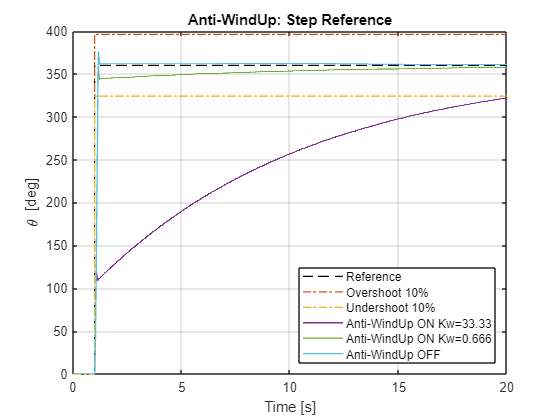

save('01_anti_windup.mat','anti_windup');

%Plotting compared results
figure

plot(anti_windup.step.thref.time, anti_windup.step.thref.signals.values,'--', 'LineWidth',1,'Color','black');
hold on;
plot(anti_windup.step.thref.time, anti_windup.step.thref.signals.values*1.10,'-.', 'LineWidth',1);
plot(anti_windup.step.thref.time, anti_windup.step.thref.signals.values*0.9,'-.', 'LineWidth',1);
plot(anti_windup.step_suggested.thl_meas.time, anti_windup.step_suggested.thl_meas.signals.values, 'LineWidth',1);
plot(anti_windup.step.thl_meas.time, anti_windup.step.thl_meas.signals.values, 'LineWidth',1);
plot(anti_windup.OFF_step.thl_meas.time, anti_windup.OFF_step.thl_meas.signals.values, 'LineWidth',1);
grid on;
legend('Reference','Overshoot 10%', 'Undershoot 10%','Anti-WindUp ON Kw=33.33','Anti-WindUp ON Kw=0.666', 'Anti-WindUp OFF','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Anti-WindUp: Step Reference');

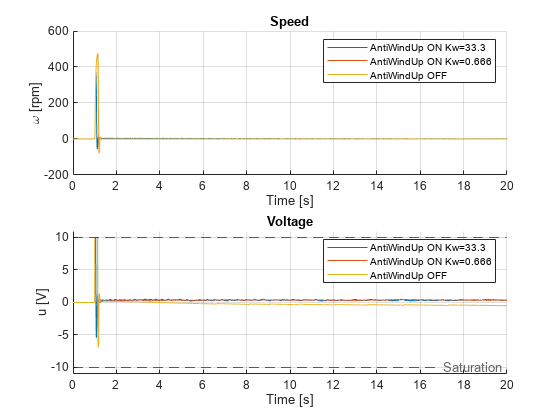

figure
subplot(2,1,1);
%plot(anti_windup.OFF_step.wref.time, anti_windup.OFF_step.wref.signals.values,'--');
hold on;
plot(anti_windup.step_suggested.wl_meas.time, anti_windup.step_suggested.wl_meas.signals.values);
plot(anti_windup.step.wl_meas.time, anti_windup.step.wl_meas.signals.values);
plot(anti_windup.OFF_step.wl_meas.time, anti_windup.OFF_step.wl_meas.signals.values);
legend('AntiWindUp ON Kw=33.3', 'AntiWindUp ON Kw=0.666', 'AntiWindUp OFF')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,1,2);
hold on;
plot(anti_windup.step_suggested.u.time, anti_windup.step_suggested.u.signals.values);
plot(anti_windup.step.u.time, anti_windup.step.u.signals.values);
plot(anti_windup.OFF_step.u.time, anti_windup.OFF_step.u.signals.values);
legend('AntiWindUp ON Kw=33.3', 'AntiWindUp ON Kw=0.666', 'AntiWindUp OFF')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','HandleVisibility','off');
yline(-10,'--','Saturation','LabelVerticalAlignment', 'middle','HandleVisibility','off');
ylim([-11 11])
title('Voltage')

### [2.2] FEED-FORWARD

simul.select1 = 3;      % takes values in {1, 2,3} = {deg, rpm, rpm/s} reference
simul.FFW = 1;          % enables FFW, set 0 to disable
awu.Kw = 0;             % Disable Anti windup

Calculating PID gains required

a = 320;                      
pid.K = dK * cos(dPh);

Td = (tan(dPh)+sqrt(tan(dPh)^2+4/a))/(2*perf.wg);
Ti = a*Td;

pid.Kd = pid.K*Td;
pid.Ki = pid.K/Ti;
disp(pid);

    Ki: 3.2823
    Kd: 0.0858
     K: 9.4929



Simulating **with** Feedforward

# DO SIMULATION

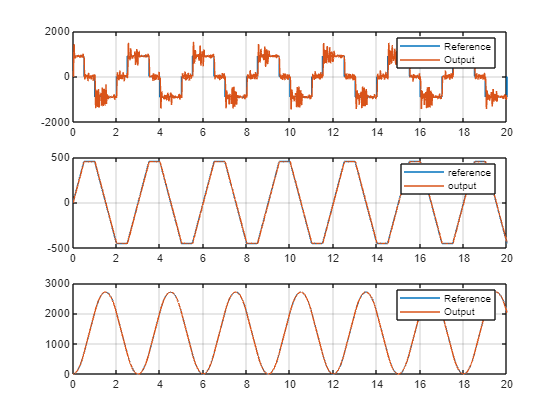



%feedforward.ON = sim('lab1_PID','StartTime','0','StopTime','9', 'AlgebraicLoopMsg', 'off');
feedforward.ON.al_meas = al_meas;
feedforward.ON.aref = aref;
feedforward.ON.e = e;
feedforward.ON.ia = ia;
feedforward.ON.thl_meas = thl_meas;
feedforward.ON.thref = thref;
feedforward.ON.u = u;
feedforward.ON.wl_meas = wl_meas;
feedforward.ON.wref = wref;
feedforward.ON.pid = pid;
feedforward.ON.simul = simul;



figure
title('Feedforward Results')
subplot(3,1,1);
plot(feedforward.ON.aref.time, feedforward.ON.aref.signals.values);
hold on;
plot(feedforward.ON.al_meas.time, feedforward.ON.al_meas.signals.values);
legend('Reference', 'Output')
grid on;
subplot(3,1,2);
plot(feedforward.ON.wref.time, feedforward.ON.wref.signals.values);
hold on;
plot(feedforward.ON.wl_meas.time, feedforward.ON.wl_meas.signals.values);
legend('reference', 'output')
grid on;
subplot(3,1,3);
plot(feedforward.ON.thref.time, feedforward.ON.thref.signals.values);
hold on;
plot(feedforward.ON.thl_meas.time, feedforward.ON.thl_meas.signals.values);
legend('Reference', 'Output')
grid on;

Simulating **without** Feedforward

simul.FFW = 0;          % enables FFW, set 0 to disable

# DO SIMULATION

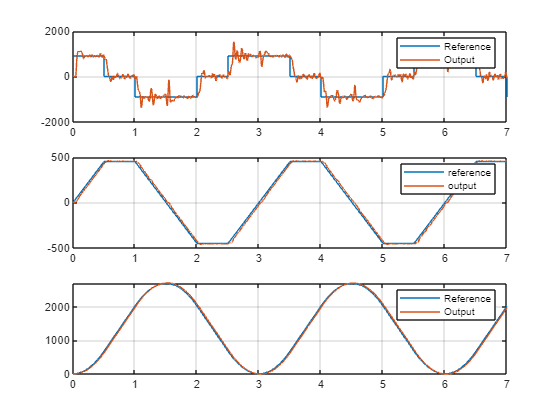

%feedforward.OFF = sim('lab1_PID','StartTime','0','StopTime','9', 'AlgebraicLoopMsg', 'off');
feedforward.OFF.al_meas = al_meas;
feedforward.OFF.aref = aref;
feedforward.OFF.e = e;
feedforward.OFF.ia = ia;
feedforward.OFF.thl_meas = thl_meas;
feedforward.OFF.thref = thref;
feedforward.OFF.u = u;
feedforward.OFF.wl_meas = wl_meas;
feedforward.OFF.wref = wref;
feedforward.OFF.pid = pid;
feedforward.OFF.simul = simul;
save('02_feedforward.mat','feedforward');

figure
title('Feedforward Results')
subplot(3,1,1);
plot(feedforward.OFF.aref.time, feedforward.OFF.aref.signals.values);
hold on;
plot(feedforward.OFF.al_meas.time, feedforward.OFF.al_meas.signals.values);
legend('Reference', 'Output')
grid on;
xlim([0 7])
subplot(3,1,2);
plot(feedforward.OFF.wref.time, feedforward.OFF.wref.signals.values);
hold on;
plot(feedforward.OFF.wl_meas.time, feedforward.OFF.wl_meas.signals.values);
legend('reference', 'output')
grid on;
xlim([0 7])
subplot(3,1,3);
plot(feedforward.OFF.thref.time, feedforward.OFF.thref.signals.values);
hold on;
plot(feedforward.OFF.thl_meas.time, feedforward.OFF.thl_meas.signals.values);
legend('Reference', 'Output')
grid on;
xlim([0 7])

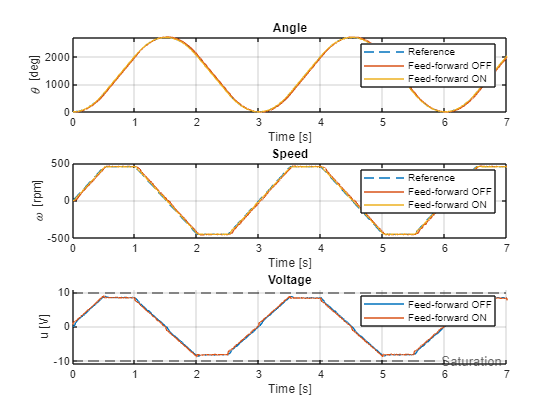

figure
title('Feedforward Results Comparison')
subplot(3,1,1);
plot(feedforward.OFF.thref.time, feedforward.OFF.thref.signals.values,'--');
hold on;
plot(feedforward.OFF.thl_meas.time, feedforward.OFF.thl_meas.signals.values);
plot(feedforward.ON.thl_meas.time, feedforward.ON.thl_meas.signals.values);
legend('Reference', 'Feed-forward OFF','Feed-forward ON')
title('Angle')
xlabel('Time [s]')
ylabel('\theta [deg]')
grid on;
xlim([0 7])
subplot(3,1,2);
plot(feedforward.OFF.wref.time, feedforward.OFF.wref.signals.values,'--');
hold on;
plot(feedforward.OFF.wl_meas.time, feedforward.OFF.wl_meas.signals.values);
plot(feedforward.ON.wl_meas.time, feedforward.ON.wl_meas.signals.values);
legend('Reference', 'Feed-forward OFF','Feed-forward ON')
title('Speed')
xlabel('Time [s]')
ylabel('\omega [rpm]')
grid on;
xlim([0 7])
subplot(3,1,3);
hold on;
plot(feedforward.OFF.u.time, feedforward.OFF.u.signals.values);
plot(feedforward.ON.u.time, feedforward.ON.u.signals.values);
legend('Feed-forward OFF','Feed-forward ON')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','HandleVisibility','off');
yline(-10,'--','Saturation','LabelVerticalAlignment', 'middle','HandleVisibility','off');
ylim([-11 11])
xlim([0 7])
title('Voltage')

## STATE SPACE

### **[3.2] Nominal Traking design **

Consider the problem of asymptotically tracking a step reference input $r\left(t\right)=r_{\infty } \delta_{-1} \left(t\right)$ in the ideal situation of perfect knowledge of the plant dynamics and lack of any external disturbance (nominal tracking problem). The perfect steady state tracking condition ${y_{\infty } =r_{\infty } }$ imposes that $x_{\infty }$ and $u_{\infty }$ satisfy the conditions


$$\left\lbrack \begin{array}{cc}
A & B\\
C & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
N_x \\
N_u 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$$


where $u=-K\;x+\left(N_u +{K\;N}_x \right)r_{\infty }$ and $K$is a state feedback gain that asymptotically stabilises the closed–loop system.

For the simulations, consider either an “ideal” situation with no static friction, or a “real” situation with a static friction torque as estimated in the previous laboratory activity. Perform the tests with three different position set–points, e.g. **40°**, **70°** and **120°**.

simul.stepdeg = 40;

# DO SIMULATION BEFORE REMEMBER TO RUN PREVIOUS SECTION

%nominal_track.deg_40 = sim('lab1_ss','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
nominal_track.deg_40.ia = ia;
nominal_track.deg_40.thl_meas = thl_meas;
nominal_track.deg_40.thref = thref;

nominal_track.deg_40.u = u;
nominal_track.deg_40.wl_meas = wl_meas;

simul.stepdeg = 70;


# DO SIMULATION

%nominal_track.deg_70 = sim('lab1_ss','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
nominal_track.deg_70.ia = ia;
nominal_track.deg_70.thl_meas = thl_meas;
nominal_track.deg_70.thref = thref;
nominal_track.deg_70.u = u;
nominal_track.deg_70.wl_meas = wl_meas;

simul.stepdeg = 120;

# DO SIMULATION

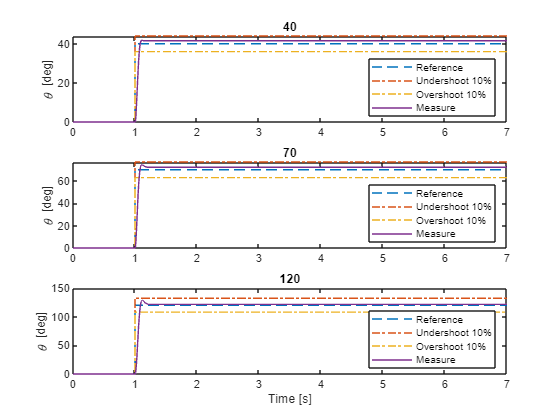

%nominal_track.deg_120 = sim('lab1_ss','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
nominal_track.deg_120.ia = ia;
nominal_track.deg_120.thl_meas = thl_meas;
nominal_track.deg_120.thref = thref;
nominal_track.deg_120.u = u;
nominal_track.deg_120.wl_meas = wl_meas;

save('03_nominal_track.mat','nominal_track');

figure
subplot(3,1,1)
plot(nominal_track.deg_40.thref.time, nominal_track.deg_40.thref.signals.values,'--');
hold on;
plot(nominal_track.deg_40.thref.time, nominal_track.deg_40.thref.signals.values*1.10,'-.');
plot(nominal_track.deg_40.thref.time, nominal_track.deg_40.thref.signals.values*0.9,'-.');
plot(nominal_track.deg_40.thl_meas.time, nominal_track.deg_40.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
title('40')
xlim([0 7])
ylabel('\theta [deg]')

subplot(3,1,2)
plot(nominal_track.deg_70.thref.time, nominal_track.deg_70.thref.signals.values,'--');
hold on;
plot(nominal_track.deg_70.thref.time, nominal_track.deg_70.thref.signals.values*1.10,'-.');
plot(nominal_track.deg_70.thref.time, nominal_track.deg_70.thref.signals.values*0.9,'-.');
plot(nominal_track.deg_70.thl_meas.time, nominal_track.deg_70.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
title('70')
xlim([0 7])
ylabel('\theta [deg]')

subplot(3,1,3)
plot(nominal_track.deg_120.thref.time, nominal_track.deg_120.thref.signals.values,'--');
hold on;
plot(nominal_track.deg_120.thref.time, nominal_track.deg_120.thref.signals.values*1.10,'-.');
plot(nominal_track.deg_120.thref.time, nominal_track.deg_120.thref.signals.values*0.9,'-.');
plot(nominal_track.deg_120.thl_meas.time, nominal_track.deg_120.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
title('120')
xlim([0 7])
xlabel('Time [s]')
ylabel('\theta [deg]')

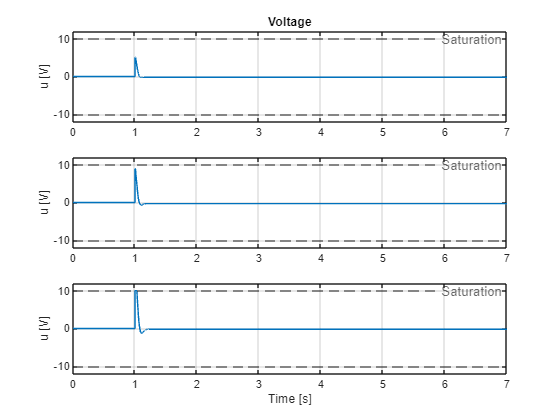

figure
subplot(3,1,1)
plot(nominal_track.deg_40.u.time, nominal_track.deg_40.u.signals.values);
hold on;
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
xlim([0 7])
title('Voltage')
grid on
subplot(3,1,2)
plot(nominal_track.deg_70.u.time, nominal_track.deg_70.u.signals.values);
hold on;
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
xlim([0 7])
grid on
subplot(3,1,3)
plot(nominal_track.deg_120.u.time, nominal_track.deg_120.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
xlim([0 7])
grid on
subplot(3,1,2)

### **[3.2] Robust Traking **

**of constant postion set-point and rejection of constant load disturbances**

In this case we consider the augmented state system


$$\left\lbrack \begin{array}{c}
\dot{x_I } \left(t\right)\\
\dot{x} \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & C\\
0 & A
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_I \left(t\right)\\
x\left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
B
\end{array}\right\rbrack u-\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack r$$


If the pair (A, B) is reachable and the open loop transfer function H(s) = C(sI − A)−1B has no zeros at s = 0, then Σe is reachable and therefore the eigenvalues of the closed–loop system, namely the eigenvalues of


$$A_{\textrm{cl}} =\left\lbrack \begin{array}{cc}
0 & C\\
-B\;K_I  & A-B\;K
\end{array}\right\rbrack$$


can be placed at arbitrary position by properly selecting the feedback gain matrix Ke.

simul.stepdeg = 40;
ssRobust.Ki = ssRobust.Ki5;
ssRobust.K = ssRobust.K5;

# DO SIMULATION BEFORE REMEMBER TO RUN PREVIOUS SECTION

%nominal_track.deg_40 = sim('lab1_ss','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
robust_track.deg_40.ia = ia;
robust_track.deg_40.thl_meas = thl_meas;
robust_track.deg_40.thref = thref;
robust_track.deg_40.u = u;
robust_track.deg_40.wl_meas = wl_meas;
stepinfo(robust_track.deg_40.thl_meas.signals.values,robust_track.deg_40.thref.time,simul.stepdeg)

ans = struct with fields:
         RiseTime: 0.0343
    TransientTime: 1.2973
     SettlingTime: 1.2973
      SettlingMin: 36.3600
      SettlingMax: 48.2400
        Overshoot: 20.6000
       Undershoot: 0
             Peak: 48.2400
         PeakTime: 1.0990


simul.stepdeg = 70;


# DO SIMULATION

%robust_track.deg_70 = sim('lab1_ss','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
robust_track.deg_70.ia = ia;
robust_track.deg_70.thl_meas = thl_meas;
robust_track.deg_70.thref = thref;
robust_track.deg_70.u = u;
robust_track.deg_70.wl_meas = wl_meas;
%stepinfo(robust_track.deg_70.thl_meas.signals.values,robust_track.deg_70.thref.time,simul.stepdeg)
simul.stepdeg = 120;

# DO SIMULATION

%robust_track.deg_120 = sim('lab1_ss','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
robust_track.deg_120.ia = ia;
robust_track.deg_120.thl_meas = thl_meas;
robust_track.deg_120.thref = thref;
robust_track.deg_120.u = u;
robust_track.deg_120.wl_meas = wl_meas;
%stepinfo(robust_track.deg_120.thl_meas.signals.values,robust_track.deg_120.thref.time,simul.stepdeg)
save('04_robust_track.mat','robust_track');

PLOTS FOR ROBUST CONTROL

simul.stepdeg=40;
stepinfo(robust_track.deg_40.thl_meas.signals.values,robust_track.deg_40.thref.time,simul.stepdeg)

ans = struct with fields:
         RiseTime: 0.0255
    TransientTime: 1.2133
     SettlingTime: 1.2133
      SettlingMin: 36.3600
      SettlingMax: 50.2200
        Overshoot: 25.5500
       Undershoot: 0
             Peak: 50.2200
         PeakTime: 1.0760


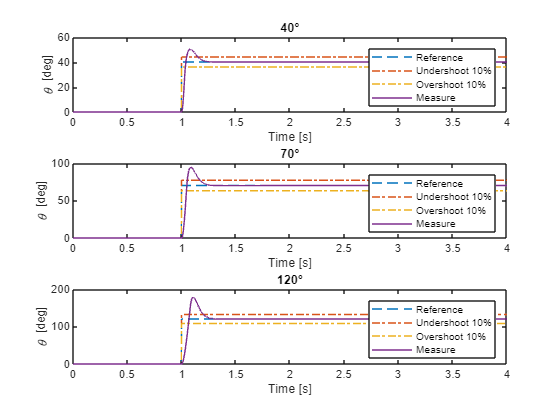

figure
subplot(3,1,1)
plot(robust_track.deg_40.thref.time, robust_track.deg_40.thref.signals.values,'--');
hold on;
plot(robust_track.deg_40.thref.time, robust_track.deg_40.thref.signals.values*1.10,'-.');
plot(robust_track.deg_40.thref.time, robust_track.deg_40.thref.signals.values*0.9,'-.');
plot(robust_track.deg_40.thl_meas.time, robust_track.deg_40.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('40°')

subplot(3,1,2)
plot(robust_track.deg_70.thref.time, robust_track.deg_70.thref.signals.values,'--');
hold on;
plot(robust_track.deg_70.thref.time, robust_track.deg_70.thref.signals.values*1.10,'-.');
plot(robust_track.deg_70.thref.time, robust_track.deg_70.thref.signals.values*0.9,'-.');
plot(robust_track.deg_70.thl_meas.time, robust_track.deg_70.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('70°')

subplot(3,1,3)
plot(robust_track.deg_120.thref.time, robust_track.deg_120.thref.signals.values,'--');
hold on;
plot(robust_track.deg_120.thref.time, robust_track.deg_120.thref.signals.values*1.10,'-.');
plot(robust_track.deg_120.thref.time, robust_track.deg_120.thref.signals.values*0.9,'-.');
plot(robust_track.deg_120.thl_meas.time, robust_track.deg_120.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('120°')

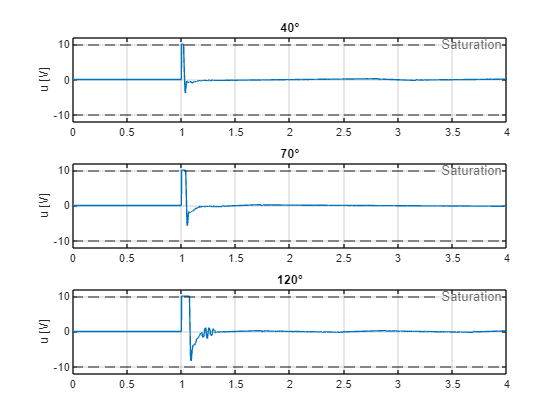

figure("Name",'Voltage')
subplot(3,1,1)
plot(robust_track.deg_40.u.time, robust_track.deg_40.u.signals.values);
hold on;
%xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
title('40°')
grid on
subplot(3,1,2)
plot(robust_track.deg_70.u.time, robust_track.deg_70.u.signals.values);
hold on;
%xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
title('70°')
grid on
subplot(3,1,3)
plot(robust_track.deg_120.u.time, robust_track.deg_120.u.signals.values);
hold on;
title('120°')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
grid on

### **[3.3] Error space**

Design a position state–space controller for the Quanser SRV–02 servomotor that guarantees the perfect steady state robust tracking of a sinusoidal position reference of a specified period Tr, and perfect rejection of constant load disturbances, using the error–space approach.

#### POINT 6 OF ASSIGNMENT

The controller for this part has already been designed in parameters.mat

SIMULATIONS

simul.select3 = 1;
ssError.ridx = 3;
ssError.freq = ssError.wrs(ssError.ridx);
ssError.amp = 30;

# DO SIMULATION BEFORE REMEMBER TO RUN PREVIOUS SECTION

%error_space.point_6.amp30 =sim('lab1_error_space','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
error_space.point_6.amp30.ia = ia;
error_space.point_6.amp30.thl_meas = thl_meas;
error_space.point_6.amp30.thref = thref;
error_space.point_6.amp30.u = u;
error_space.point_6.amp30.wl_meas = wl_meas;

ssError.amp = 60;


# DO SIMULATION

%error_space.point_6.amp60 =sim('lab1_error_space','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
error_space.point_6.amp60.ia = ia;
error_space.point_6.amp60.thl_meas = thl_meas;
error_space.point_6.amp60.thref = thref;
error_space.point_6.amp60.u = u;
error_space.point_6.amp60.wl_meas = wl_meas;

ssError.amp = 90;

# DO SIMULATION

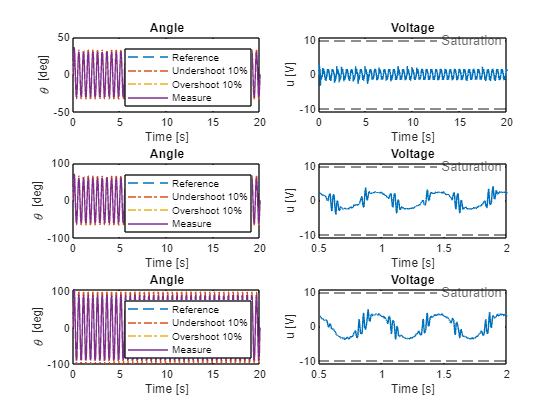

%error_space.point_6.amp90 =sim('lab1_error_space','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
error_space.point_6.amp90.ia = ia;
error_space.point_6.amp90.thl_meas = thl_meas;
error_space.point_6.amp90.thref = thref;
error_space.point_6.amp90.u = u;
error_space.point_6.amp90.wl_meas = wl_meas;

figure("Name",'Results')
subplot(3,2,1)
plot(error_space.point_6.amp30.thref.time, error_space.point_6.amp30.thref.signals.values,'--');
hold on;
plot(error_space.point_6.amp30.thref.time, error_space.point_6.amp30.thref.signals.values*1.10,'-.');
plot(error_space.point_6.amp30.thref.time, error_space.point_6.amp30.thref.signals.values*0.9,'-.');
plot(error_space.point_6.amp30.thl_meas.time, error_space.point_6.amp30.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,2)
plot(error_space.point_6.amp30.u.time, error_space.point_6.amp30.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')


subplot(3,2,3)
plot(error_space.point_6.amp60.thref.time, error_space.point_6.amp60.thref.signals.values,'--');
hold on;
plot(error_space.point_6.amp60.thref.time, error_space.point_6.amp60.thref.signals.values*1.10,'-.');
plot(error_space.point_6.amp60.thref.time, error_space.point_6.amp60.thref.signals.values*0.9,'-.');
plot(error_space.point_6.amp60.thl_meas.time, error_space.point_6.amp60.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,4)
plot(error_space.point_6.amp60.u.time, error_space.point_6.amp60.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
xlim([0.5 2])
title('Voltage')


subplot(3,2,5)
plot(error_space.point_6.amp90.thref.time, error_space.point_6.amp90.thref.signals.values,'--');
hold on;
plot(error_space.point_6.amp90.thref.time, error_space.point_6.amp90.thref.signals.values*1.10,'-.');
plot(error_space.point_6.amp90.thref.time, error_space.point_6.amp90.thref.signals.values*0.9,'-.');
plot(error_space.point_6.amp90.thl_meas.time, error_space.point_6.amp90.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,6)
plot(error_space.point_6.amp90.u.time, error_space.point_6.amp90.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
xlim([0.5 2])
title('Voltage')

#### POINT 7 OF THE ASSIGMENT

the behaviuor in the plot is normal since we are using a controller design for a specific sinusoid frequency at a different frequency


%%% Reference frequencies
ssError.amp = 40;                    % Choose sinusoide amplitude
ssError.freq = 2*pi/0.1;    % Trs = 0.1s -> w[rad/s];

# DO SIMULATION BEFORE REMEMBER TO RUN PREVIOUS SECTION

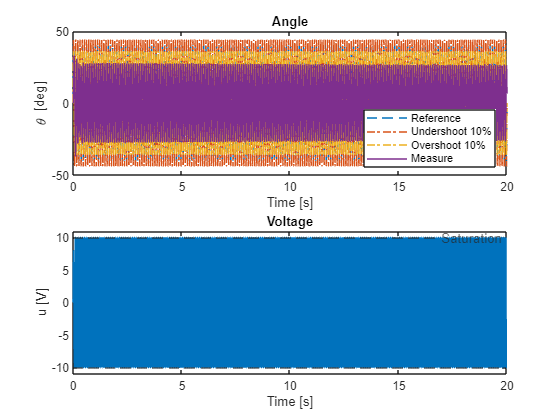

%error_space.point_7 =sim('lab1_error_space','StartTime','0','StopTime','5', 'AlgebraicLoopMsg', 'off');
error_space.point_7.ia = ia;
error_space.point_7.thl_meas = thl_meas;
error_space.point_7.thref = thref;
error_space.point_7.u = u;
error_space.point_7.wl_meas = wl_meas;

figure("Name",'Results')
subplot(2,1,1)
plot(error_space.point_7.thref.time, error_space.point_7.thref.signals.values,'--');
hold on;
plot(error_space.point_7.thref.time, error_space.point_7.thref.signals.values*1.10,'-.');
plot(error_space.point_7.thref.time, error_space.point_7.thref.signals.values*0.9,'-.');
plot(error_space.point_7.thl_meas.time, error_space.point_7.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(2,1,2)
plot(error_space.point_7.u.time, error_space.point_7.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')

#### POINT 8 OF THE ASSIGMENT


%%% Reference frequencies
simul.select3 = 2;
ssError.amp = 40;                    % Choose sinusoide amplitude

# DO SIMULATION BEFORE REMEMBER TO RUN PREVIOUS SECTION

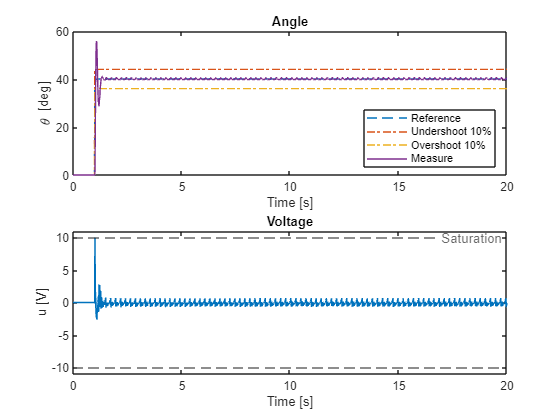

%error_space.point_8 =sim('lab1_error_space','StartTime','0','StopTime','5', 'AlgebraicLoopMsg', 'off');
error_space.point_8.ia = ia;
error_space.point_8.thl_meas = thl_meas;
error_space.point_8.thref = thref;
error_space.point_8.u = u;
error_space.point_8.wl_meas = wl_meas;

save('05_error_space.mat','error_space');

figure("Name",'Results')
subplot(2,1,1)
plot(error_space.point_8.thref.time, error_space.point_8.thref.signals.values,'--');
hold on;
plot(error_space.point_8.thref.time, error_space.point_8.thref.signals.values*1.10,'-.');
plot(error_space.point_8.thref.time, error_space.point_8.thref.signals.values*0.9,'-.');
plot(error_space.point_8.thl_meas.time, error_space.point_8.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(2,1,2)
plot(error_space.point_8.u.time, error_space.point_8.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')

### [Bonus] Extended Estimator

#### ESTIMATOR POINT 6

The controller for this part has already been designed in parameters.mat

SIMULATIONS

simul.select3 = 1;
ssError.ridx = 3;
ssError.freq = ssError.wrs(ssError.ridx);
ssError.amp = 30;

# DO SIMULATION BEFORE REMEMBER TO RUN PREVIOUS SECTION

%extended_estimator.point_6.amp30 =sim('lab1_extended_estimator','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
extended_estimator.point_6.amp30.ia = ia;
extended_estimator.point_6.amp30.thl_meas = thl_meas;
extended_estimator.point_6.amp30.thref = thref;
extended_estimator.point_6.amp30.u = u;
extended_estimator.point_6.amp30.wl_meas = wl_meas;

ssError.amp = 60;

# DO SIMULATION

%extended_estimator.point_6.amp60 =sim('lab1_extended_estimator','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
extended_estimator.point_6.amp60.ia = ia;
extended_estimator.point_6.amp60.thl_meas = thl_meas;
extended_estimator.point_6.amp60.thref = thref;
extended_estimator.point_6.amp60.u = u;
extended_estimator.point_6.amp60.wl_meas = wl_meas;

ssError.amp = 90;

# DO SIMULATION

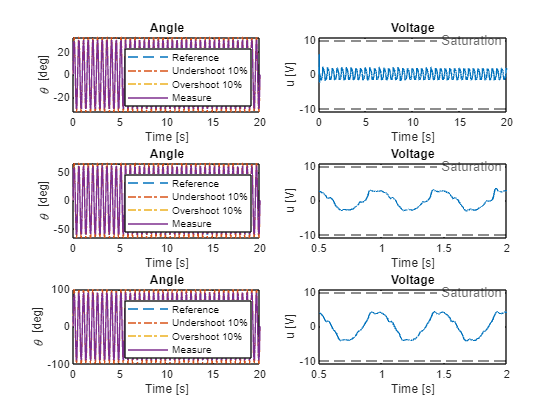

%extended_estimator.point_6.amp90 =sim('lab1_extended_estimator','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
extended_estimator.point_6.amp90.ia = ia;
extended_estimator.point_6.amp90.thl_meas = thl_meas;
extended_estimator.point_6.amp90.thref = thref;
extended_estimator.point_6.amp90.u = u;
extended_estimator.point_6.amp90.wl_meas = wl_meas;


figure("Name",'Results')
subplot(3,2,1)
plot(extended_estimator.point_6.amp30.thref.time, extended_estimator.point_6.amp30.thref.signals.values,'--');
hold on;
plot(extended_estimator.point_6.amp30.thref.time, extended_estimator.point_6.amp30.thref.signals.values*1.10,'-.');
plot(extended_estimator.point_6.amp30.thref.time, extended_estimator.point_6.amp30.thref.signals.values*0.9,'-.');
plot(extended_estimator.point_6.amp30.thl_meas.time, extended_estimator.point_6.amp30.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,2)
plot(extended_estimator.point_6.amp30.u.time, extended_estimator.point_6.amp30.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')


subplot(3,2,3)
plot(extended_estimator.point_6.amp60.thref.time, extended_estimator.point_6.amp60.thref.signals.values,'--');
hold on;
plot(extended_estimator.point_6.amp60.thref.time, extended_estimator.point_6.amp60.thref.signals.values*1.10,'-.');
plot(extended_estimator.point_6.amp60.thref.time, extended_estimator.point_6.amp60.thref.signals.values*0.9,'-.');
plot(extended_estimator.point_6.amp60.thl_meas.time, extended_estimator.point_6.amp60.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,4)
plot(extended_estimator.point_6.amp60.u.time, extended_estimator.point_6.amp60.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
xlim([0.5 2])
title('Voltage')


subplot(3,2,5)
plot(extended_estimator.point_6.amp90.thref.time, extended_estimator.point_6.amp90.thref.signals.values,'--');
hold on;
plot(extended_estimator.point_6.amp90.thref.time, extended_estimator.point_6.amp90.thref.signals.values*1.10,'-.');
plot(extended_estimator.point_6.amp90.thref.time, extended_estimator.point_6.amp90.thref.signals.values*0.9,'-.');
plot(extended_estimator.point_6.amp90.thl_meas.time, extended_estimator.point_6.amp90.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,6)
plot(extended_estimator.point_6.amp90.u.time, extended_estimator.point_6.amp90.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
xlim([0.5 2])
title('Voltage')

#### ESTIMATOR POINT 7

Repeat the test above of point 6 with a sinusoidal reference input of amplitude Ar = 40° and period Tr = 0.1 (but with the control designed to track a reference sinusoid with period Tr = 0.5 s). Compare the tracking error with that obtained in the previous case. 

The behaviuor of the plot is normal since we are using a controller design for a specific sinusoid frequency at a different frequency. In particular the controller works five times slower than the refernce.

ssError.amp =40;
% In this case we select a different frequency
ssError.freq = 2*pi./0.1;

# DO SIMULATION BEFORE REMEMBER TO RUN PREVIOUS SECTION

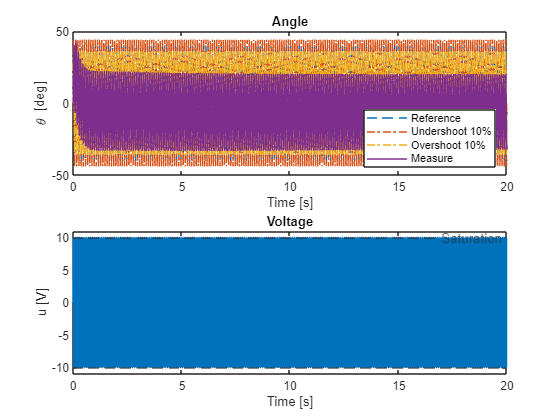

%extended_estimator.point_7 =sim('lab1_extended_estimator','StartTime','0','StopTime','5', 'AlgebraicLoopMsg', 'off');
extended_estimator.point_7.ia = ia;
extended_estimator.point_7.thl_meas = thl_meas;
extended_estimator.point_7.thref = thref;
extended_estimator.point_7.u = u;
extended_estimator.point_7.wl_meas = wl_meas;

figure("Name",'Results')
subplot(2,1,1)
plot(extended_estimator.point_7.thref.time, extended_estimator.point_7.thref.signals.values,'--');
hold on;
plot(extended_estimator.point_7.thref.time, extended_estimator.point_7.thref.signals.values*1.10,'-.');
plot(extended_estimator.point_7.thref.time, extended_estimator.point_7.thref.signals.values*0.9,'-.');
plot(extended_estimator.point_7.thl_meas.time, extended_estimator.point_7.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(2,1,2)
plot(extended_estimator.point_7.u.time, extended_estimator.point_7.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')

#### ESTIMATOR POINT 8

 Repeat the test above of point 6 with a sinusoidal reference input of amplitude Ar = 40°

% Reference setting - invariate from point 7 apart from sine frequency
simul.select3 = 2;
ssError.amp =40;


# DO SIMULATION BEFORE REMEMBER TO RUN PREVIOUS SECTION

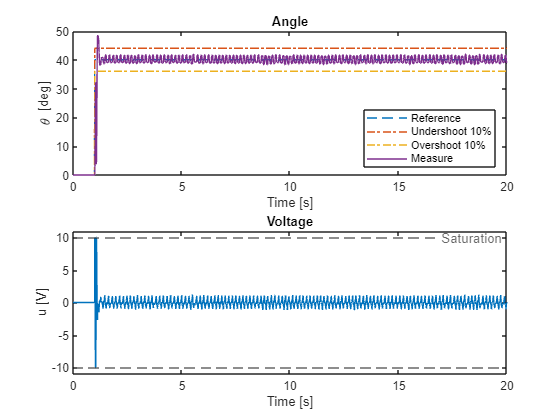

%extended_estimator.point_8 =sim('lab1_extended_estimator','StartTime','0','StopTime','5', 'AlgebraicLoopMsg', 'off');
extended_estimator.point_8.ia = ia;
extended_estimator.point_8.thl_meas = thl_meas;
extended_estimator.point_8.thref = thref;
extended_estimator.point_8.u = u;
extended_estimator.point_8.wl_meas = wl_meas;

save('06_extended_estimator.mat','extended_estimator');

figure("Name",'Results')
subplot(2,1,1)
plot(extended_estimator.point_8.thref.time, extended_estimator.point_8.thref.signals.values,'--');
hold on;
plot(extended_estimator.point_8.thref.time, extended_estimator.point_8.thref.signals.values*1.10,'-.');
plot(extended_estimator.point_8.thref.time, extended_estimator.point_8.thref.signals.values*0.9,'-.');
plot(extended_estimator.point_8.thl_meas.time, extended_estimator.point_8.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(2,1,2)
plot(extended_estimator.point_8.u.time, extended_estimator.point_8.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')

### **CHALLENGE**

We want to reach the smallest rise time possible, compatible with an overshoot of 10%. We consider as input a step of 10V amplitude in order to reach the fastest possible response.

simul.stepdeg = 70;

awu.a = 2.1;              % this should be adjusted
awu.Tw = perf.ts5/awu.a;
awu.Kw = 1/awu.Tw;


simul.FFW = 1;          % enables FFW, set 0 to disable
pid.K=65;
pid.Ki=5;
end_step=1.048;

# DO SIMULATION

%lab1_challenge = sim('lab1_challenge','StartTime','0','StopTime','2', 'AlgebraicLoopMsg', 'off');
lab1_challenge.al_meas = al_meas;
lab1_challenge.e = e;
lab1_challenge.ia = ia;
lab1_challenge.thl_meas = thl_meas;
lab1_challenge.thref = thref;
lab1_challenge.u = u;
lab1_challenge.wl_meas = wl_meas;
lab1_challenge.pid = pid;
lab1_challenge.awu = awu;
lab1_challenge.simul = simul;

save('07_lab1_challenge.mat','lab1_challenge');

stepinfo(lab1_challenge.thl_meas.signals.values,lab1_challenge.thref.time,simul.stepdeg)

ans = struct with fields:
         RiseTime: 0.0327
    TransientTime: 34.6041
     SettlingTime: 34.6041
      SettlingMin: 41.7600
      SettlingMax: 76.3200
        Overshoot: 9.0286
       Undershoot: 0
             Peak: 76.3200
         PeakTime: 1.0600


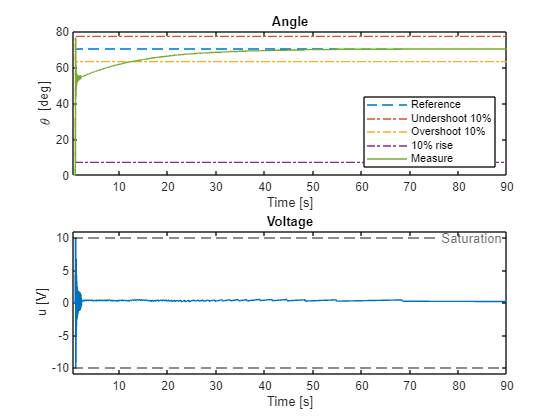

figure("Name",'Results')
subplot(2,1,1)
plot(lab1_challenge.thref.time, lab1_challenge.thref.signals.values,'--');
hold on;
plot(lab1_challenge.thref.time, lab1_challenge.thref.signals.values*1.10,'-.');
plot(lab1_challenge.thref.time, lab1_challenge.thref.signals.values*0.9,'-.');
plot(lab1_challenge.thref.time, lab1_challenge.thref.signals.values*0.1,'-.');
plot(lab1_challenge.thl_meas.time, lab1_challenge.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%','10% rise', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
xlim([0.5 90])
subplot(2,1,2)
plot(lab1_challenge.u.time, lab1_challenge.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
xlim([0.5 90])
title('Voltage')